# Exercise (1.8):

## Perform the following steps of image processing using the functions of MATLAB: 

**1. use the fspecial command to create the sobel filters and apply them to the image. Check your results from the previous task with them.**

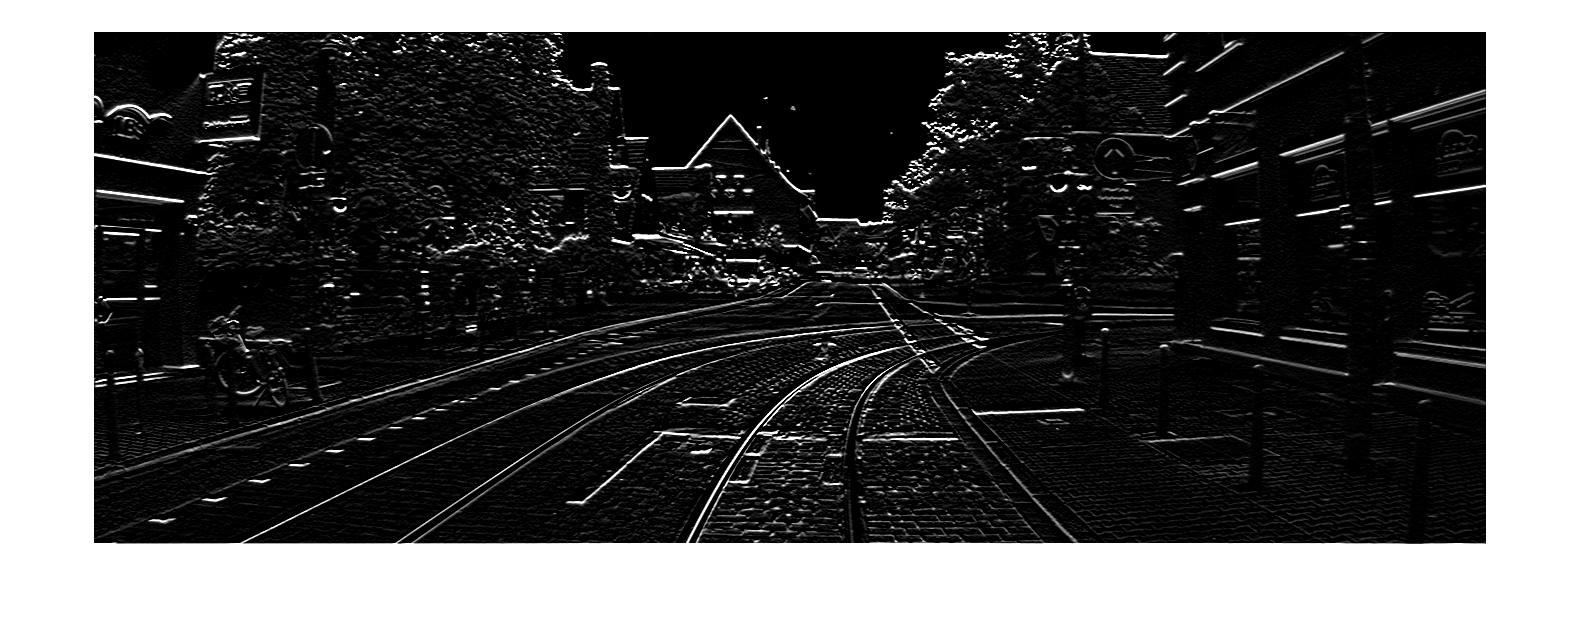

img1 = imread("0001.png");
img1_gray = int16(im2gray(img1));
sobel_v = fspecial("sobel");
sobel_h = sobel_v';
img1_sobel_v = imfilter(img1,sobel_v);
img1_sobel_h = imfilter(img1,sobel_h);
imshow(img1_sobel_v)

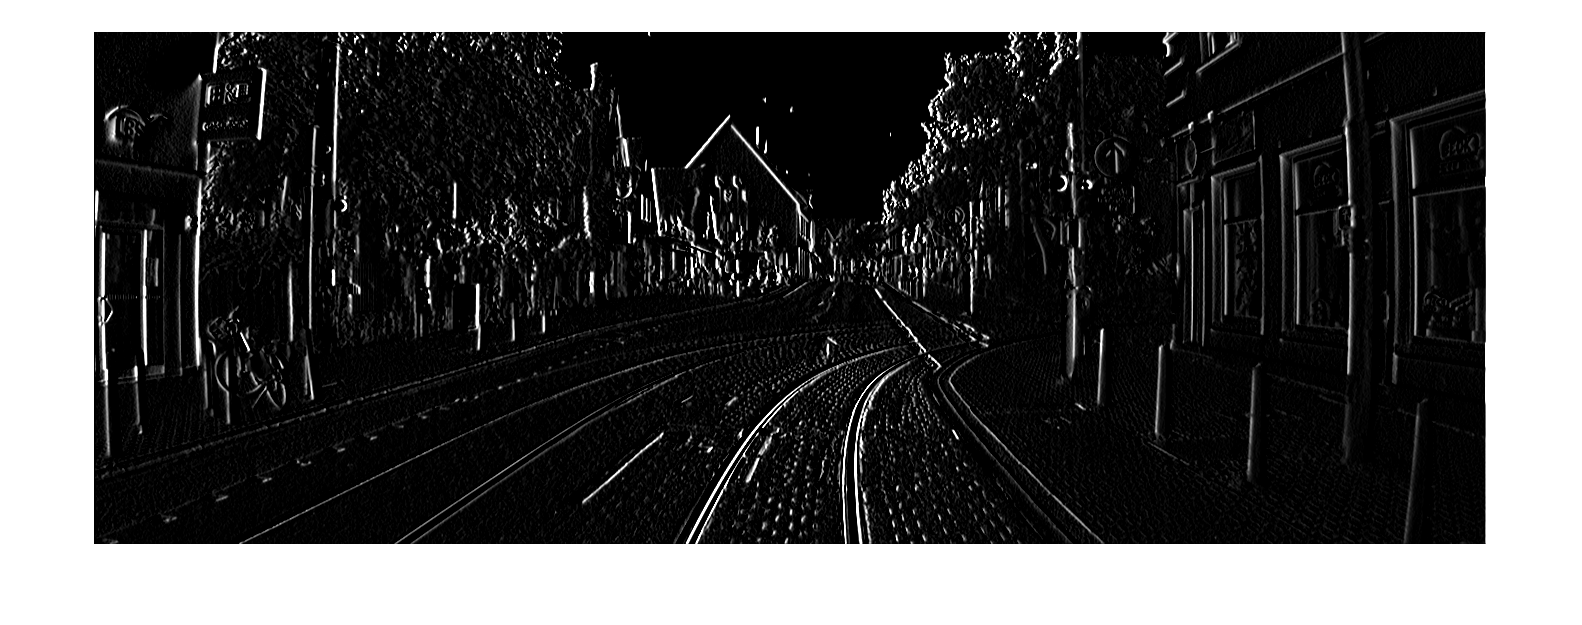

imshow(img1_sobel_h)

**2.  from your previous result generate an image that contains for each pixel the gradient length of the original image. **

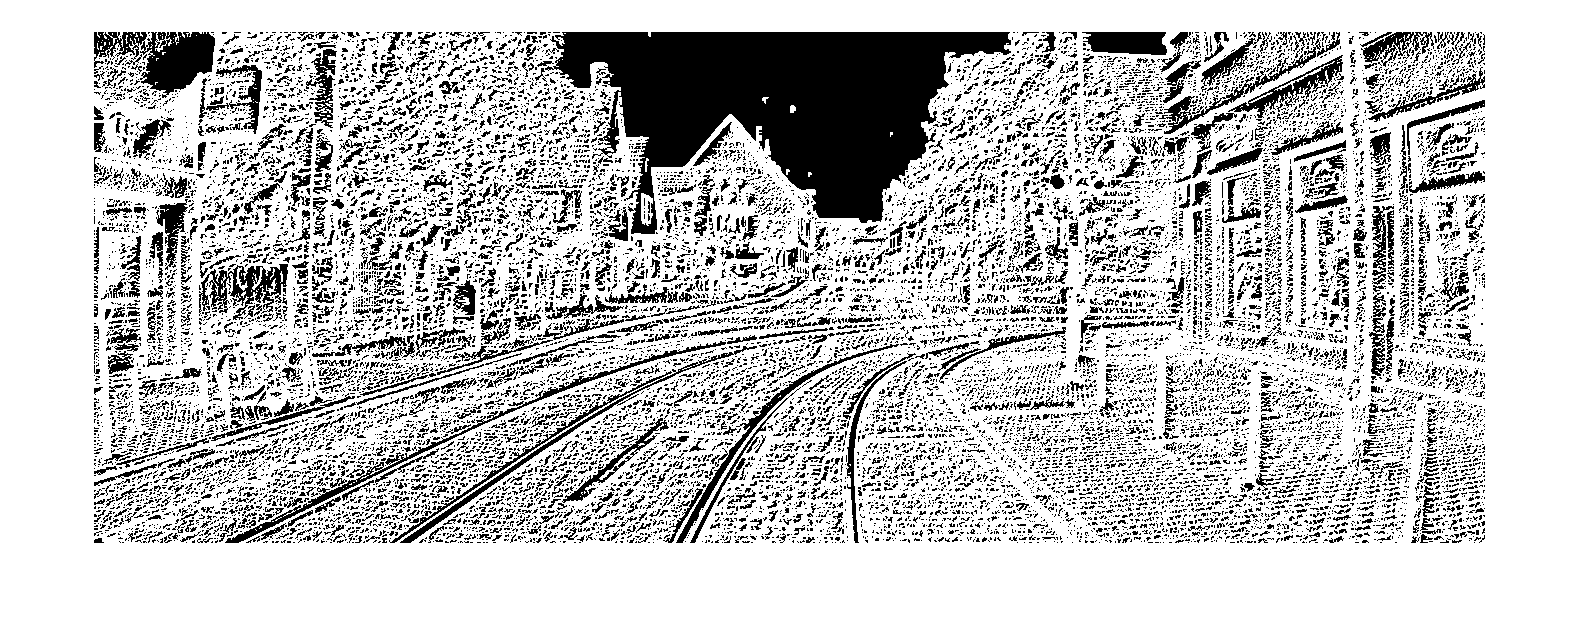

img_gradient = sqrt(double(img1_sobel_h).^2 + double(img1_sobel_v).^2);
imshow(img_gradient)

**3. create a Gaussian filter mask of size 11 and σ = 4. Convolute the grey level image ’0001.png’ with the Gaussian filter mask and display the result. Try different values for the size and σ and look at the effects.**

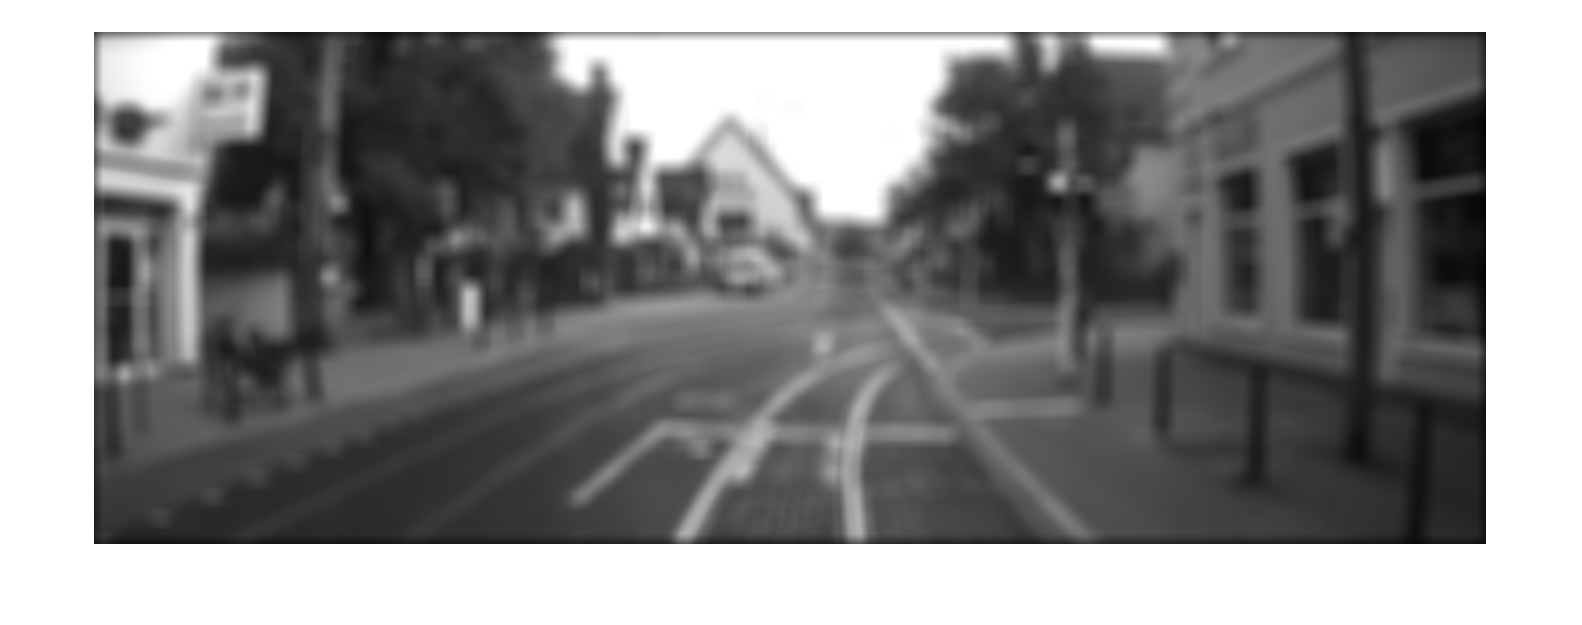

gaussian_filter = fspecial("gaussian",20,10);
img1_gaus = uint8(imfilter(img1_gray, gaussian_filter));
imshow(img1_gaus)

**4. apply the Canny edge detection algorithm to the six images 0001.png, 2176.png, 3526.png, 3964.png, 4083.png, and 4886.png. Vary the parameters of the Canny method to obtain good results.**

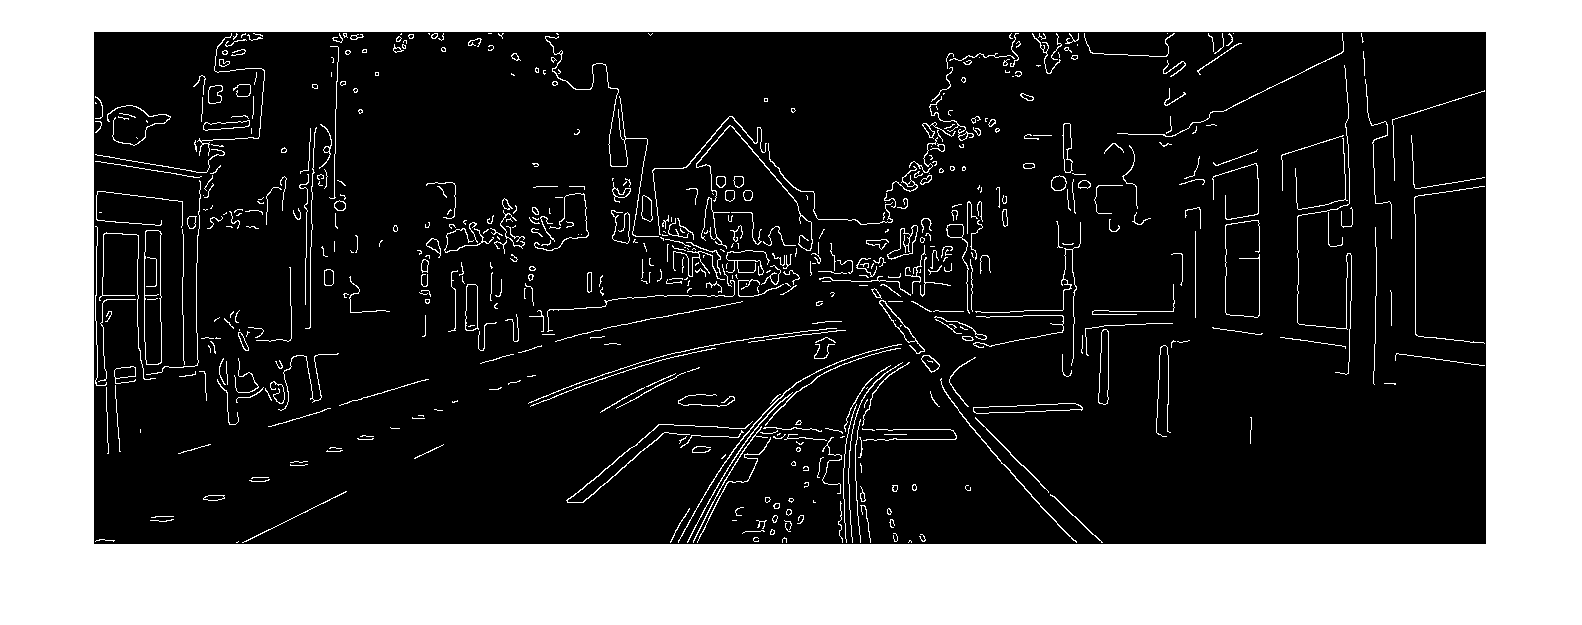

%load images
img_0001 = imread("0001.png");
img_2176 = imread("2176.png");
img_3526 = imread("3526.png");
img_3964 = imread("3964.png");

%apply canny edge detection
img_0001_canny = edge(img_0001,"canny",[0.15 0.2]);
img_2176_canny = edge(img_2176,"canny", [0.1 0.15]);
img_3526_canny = edge(img_3526,"canny",[0.1 0.15]);
img_3964_canny = edge(img_3964,"canny",[0.1 0.15]);

%show canny detected edges
imshow(img_0001_canny)

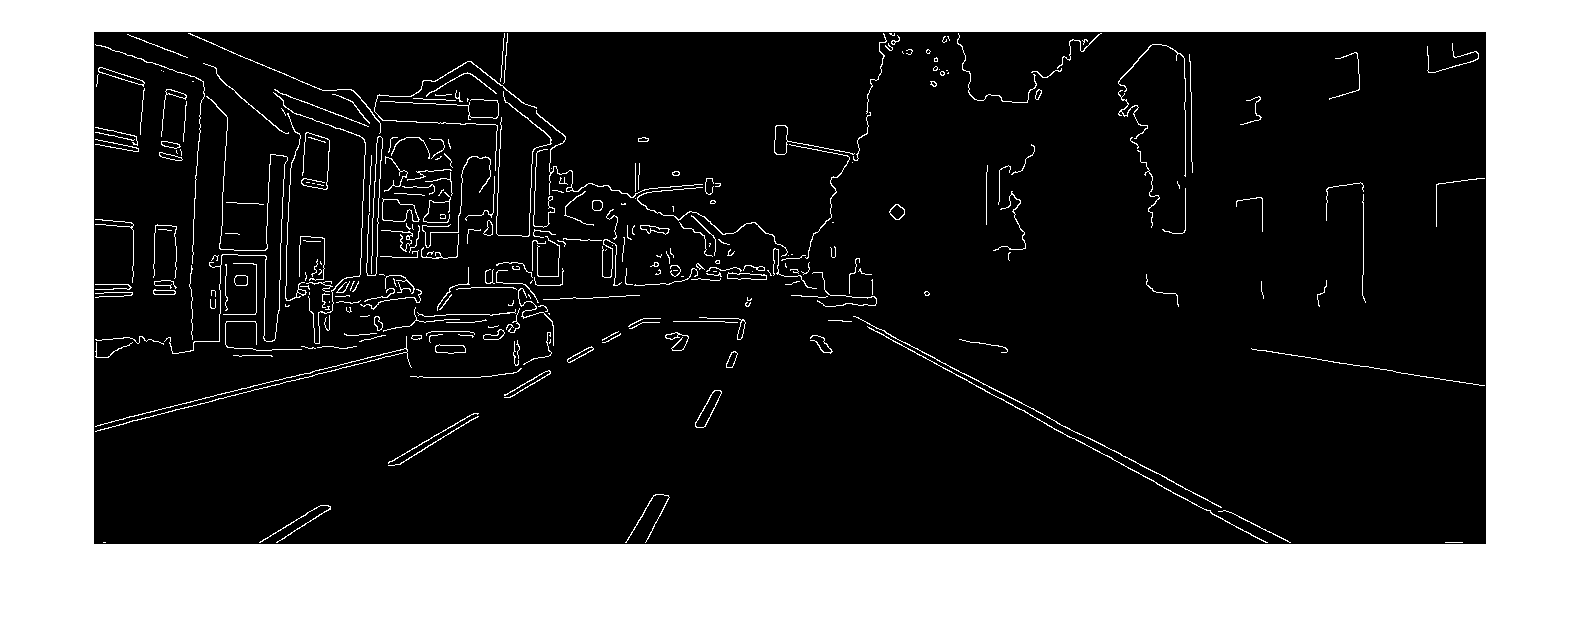

imshow(img_2176_canny)

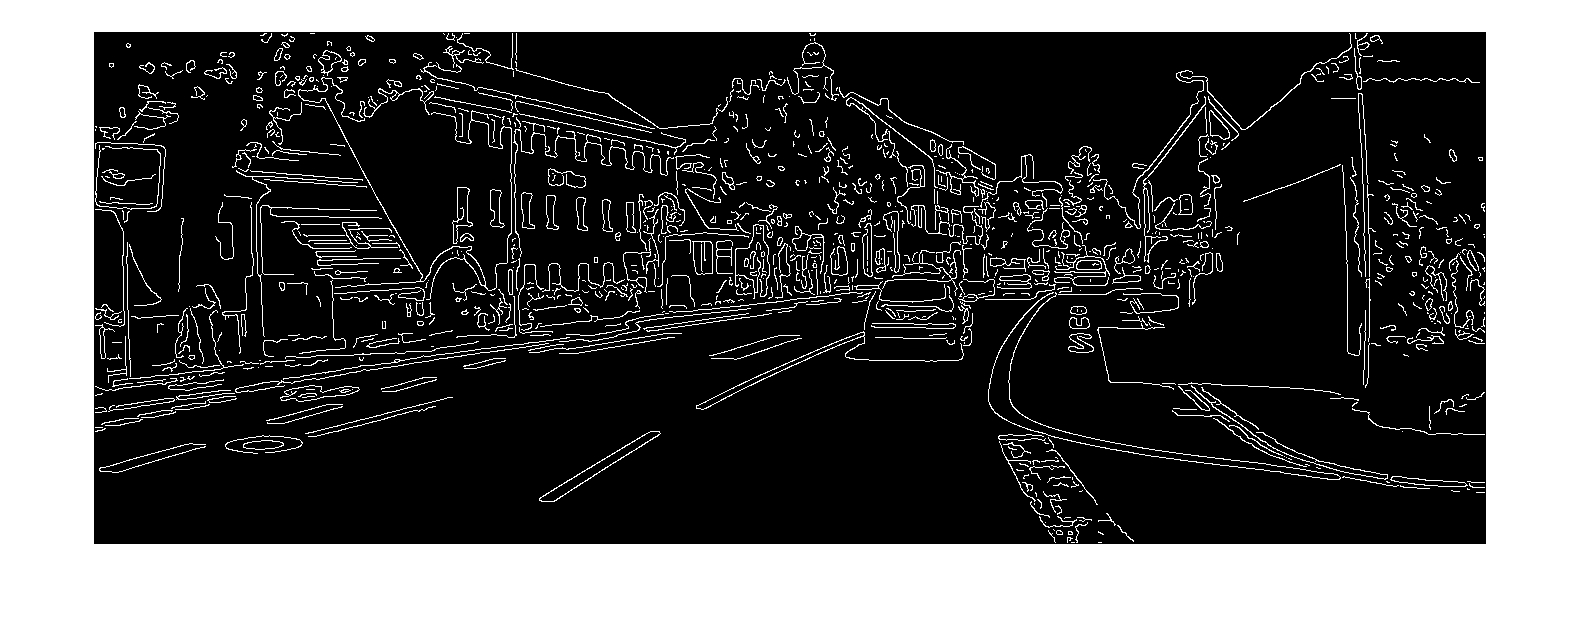

imshow(img_3526_canny)

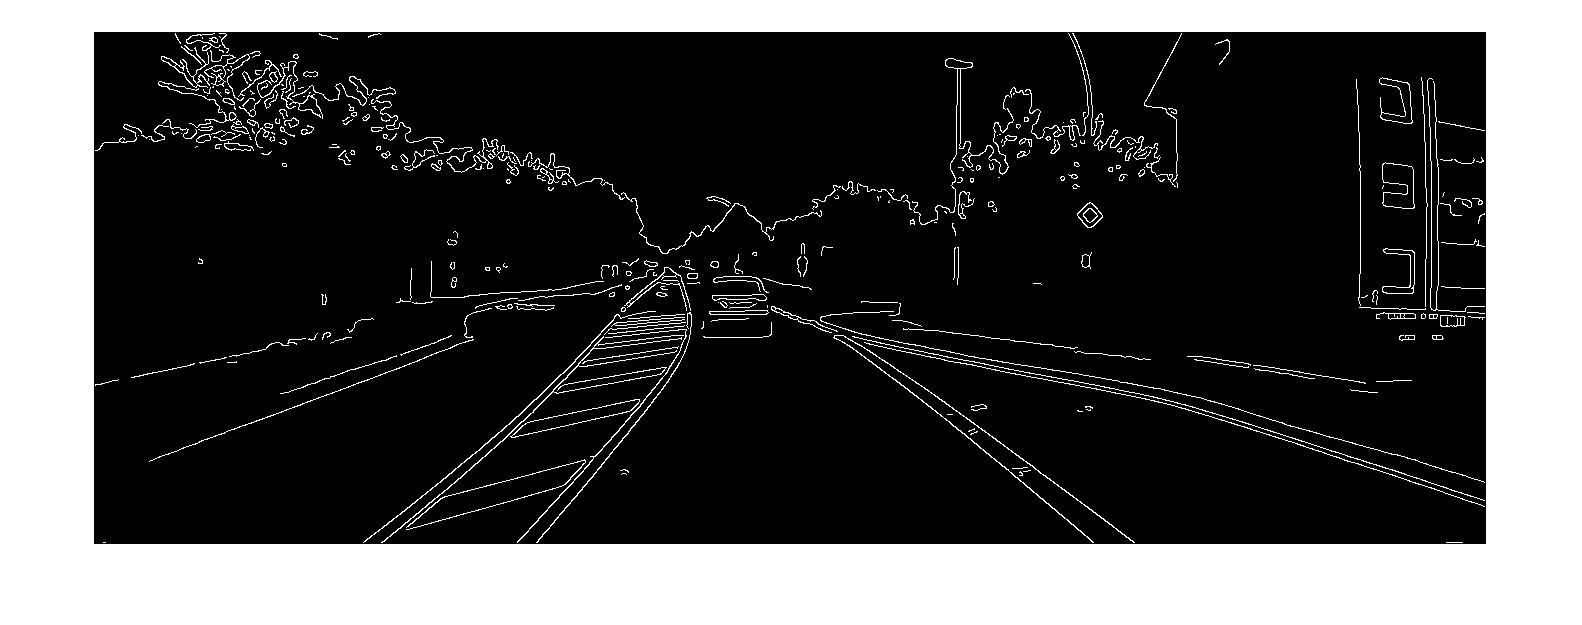

imshow(img_3964_canny)